% Set up the Import Options and import the data
opts = spreadsheetImportOptions("NumVariables", 14);

% Specify sheet and range
opts.Sheet = "Train";
opts.DataRange = "A2:N12621";

% Specify column names and types
opts.VariableNames = ["Ejerlejlighed", "AntalV_relser", "Enhedsareal_Beboelse", "Enhedsareal_Erhverv", "K_lderareal", "Familieoverdragelse", "Fritidsbolig", "Landbrugsbolig", "Energim_rke", "Opf_relses_r", "Omtilbygnings_r", "Grundareal", "Postnr", "Handelspris"];
opts.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
data_train = readtable("/Users/magnusiversen/Documents/CBS - Cand.Merc.(mat.)/Speciale/Data_v7.xlsx", opts, "UseExcel", false);

% Clear temporary variables
clear opts

% Display results
data_train

data_train = 12620×14 table
    Ejerlejlighed    AntalV_relser    Enhedsareal_Beboelse    Enhedsareal_Erhverv    K_lderareal    Familieoverdragelse    Fritidsbolig    Landbrugsbolig    Energim_rke    Opf_relses_r    Omtilbygnings_r    Grundareal    Postnr    Handelspris
    _____________    _____________    ____________________    ___________________    ___________    ___________________    ____________    ______________    ___________    ____________    _______________    __________    ______    ___________

         

% Set up the Import Options and import the data
opts2 = spreadsheetImportOptions("NumVariables", 14);

% Specify sheet and range
opts2.Sheet = "Test";
opts2.DataRange = "A2:N3157";

% Specify column names and types
opts2.VariableNames = ["Ejerlejlighed", "AntalV_relser", "Enhedsareal_Beboelse", "Enhedsareal_Erhverv", "K_lderareal", "Familieoverdragelse", "Fritidsbolig", "Landbrugsbolig", "Energim_rke", "Opf_relses_r", "Omtilbygnings_r", "Grundareal", "Postnr", "Handelspris"];
opts2.VariableTypes = ["double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double"];

% Import the data
data_test = readtable("/Users/magnusiversen/Documents/CBS - Cand.Merc.(mat.)/Speciale/Data_v7.xlsx", opts2, "UseExcel", false);

% Clear temporary variables
clear opts2

% Display results
data_test

data_test = 3156×14 table
    Ejerlejlighed    AntalV_relser    Enhedsareal_Beboelse    Enhedsareal_Erhverv    K_lderareal    Familieoverdragelse    Fritidsbolig    Landbrugsbolig    Energim_rke    Opf_relses_r    Omtilbygnings_r    Grundareal    Postnr    Handelspris
    _____________    _____________    ____________________    ___________________    ___________    ___________________    ____________    ______________    ___________    ____________    _______________    __________    ______    ___________

          0

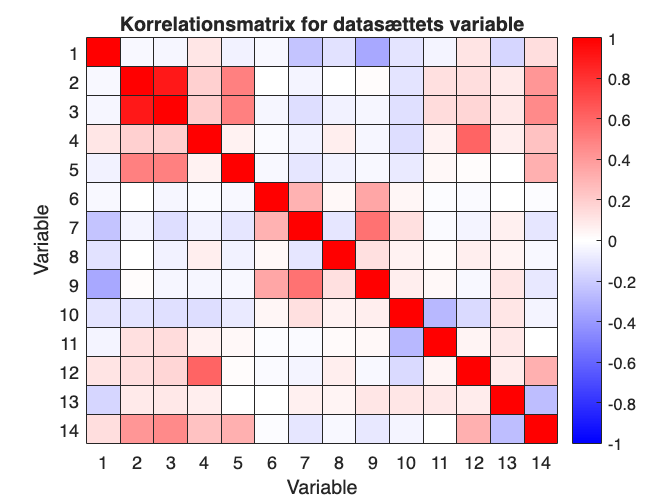

data_train = table2array(data_train);
data_test = table2array(data_test);

data_train = data_train(all(isfinite(data_train), 2), :);
data_test = data_test(all(isfinite(data_test), 2), :);

middelTrainInputs = mean(data_train(:,1:end-1));
stdTrainInputs = std(data_train(:,1:end-1));
stdTrainInputs(stdTrainInputs == 0) = 1;

trainDataInputsScaled = (data_train(:,1:end-1) - middelTrainInputs) ./ stdTrainInputs;

meanTrainTarget = mean(data_train(:,end));
stdTrainTarget = std(data_train(:,end));

if stdTrainTarget == 0
    stdTrainTarget = 1;
end

trainDataTargetScaled = (data_train(:,end) - meanTrainTarget) ./ stdTrainTarget;

trainData = [trainDataInputsScaled, trainDataTargetScaled];

testDataInputsScaled = (data_test(:,1:end-1) - middelTrainInputs) ./ stdTrainInputs;
testDataTargetScaled = (data_test(:,end) - meanTrainTarget) ./ stdTrainTarget;

testData = [testDataInputsScaled, testDataTargetScaled];

data_combined = [trainData; testData];

corrMatrix = corr(data_combined, 'Rows', 'pairwise');

figure;
heatmap(corrMatrix);
colormap(redblue); 
colorbar; 

clim([-1, 1]);

xlabel('Variable');
ylabel('Variable');
title('Korrelationsmatrix for datasættets variable');


threshold = 0.8;

highCorr = abs(corrMatrix) > threshold;

for i = 1:size(highCorr, 1)
    highCorr(i, i) = false;
end

[rows, cols] = find(highCorr);
uniquePairs = rows < cols;
for i = 1:length(uniquePairs)
    if uniquePairs(i)
        fprintf('Variable %d og %d har en correlation på %0.2f\n', rows(i), cols(i), corrMatrix(rows(i), cols(i)));
    end
end

Variable 2 og 3 har en correlation på 0.90
